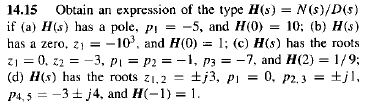

clc, clear, close all
format short g
syms s c

**a) **sabemos que los polos son los ceros en el denominador de la función, tenemos que encontrar la constente que lo vuelve cero

p1 = -5; %cuando s es igual a -5
den_s = solve(p1+c==0,c) %constante

$$den\_s = 5$$

den_s = s+5

$$den\_s = s+5$$

teniendo el denominador, cuando la funcion se evalua en cero, debe dar como resultado 10, encontramos la constante que lo satisface

s = 0;
c = solve (c/(s+5)==10,c)

$$c = 50$$

entonces

h = c/den_s

$$h = \frac{50}{s+5}$$

**b)** teniendo el cuenta el analisis anterior lo resolvemos rapidamente

syms s c
z1 = -10e3;
r = 1;

de acuerdo con la informacion suministrada sabemos que la funcion de transferencia tiene esta forma

h = c*(s+10e3)

$$h = c\,\left(s+10000\right)$$

Ahora encontramos la constante que satisface que cuando s = 0, da como resultado 1

s = 0;
c = solve(c*(s+10e3)==1,c)

$$c = \frac{1}{10000}$$

entonces

syms s
h = c*(s+10e3)

$$h = \frac{s}{10000}+1$$

**c) **

syms c
z1 = 0;
z2 = -3;
p1 = -1;
p2 = p1;
p3 = -7;
r = 1/9;

de acuerdo con la informacion suministrada sabemos que la funcion de transferencia tiene esta forma

h = c*(s*(s+3))/((s+7)*(s+1)^2)

$$h = \frac{c\,s\,\left(s+3\right)}{{\left(s+1\right)}^{2}\,\left(s+7\right)}$$

Ahora encontramos la constante que satisface que cuando s = 2, da como resultado 1/9

s = 2;
c = solve(c*(s*(s+3))/((s+7)*(s+1)^2)==r,c)

$$c = \frac{9}{10}$$

entonces

syms s
h = simplify(c*(s*(s+3))/((s+7)*(s+1)^2))

$$h = \frac{9\,s\,\left(s+3\right)}{10\,{\left(s+1\right)}^{2}\,\left(s+7\right)}$$

**d) **

syms c
z1 = j*3;
z2 = -j*3;
p1 = 0;
p2 = j;
p3 = -j;
p4 = -3+4*j;
p5 = -3-4*j;
r = 1;

construimos los polinomios del numerador y denominador a partir de sus raices con la funcion poly que nos devuelve una matriz con los coeficientes de cada grado del polinomio ordenados de mayor a menor grado

num_h = poly([z1 z2])

num_h =      1     0     9


den_h = poly([p1 p2 p3 p4 p5])

den_h =      1     6    26     6    25     0


De acuerdo con lo anterior, sabemos que h es de la siguiente forma

h = c*((num_h(1,1).*s^2+num_h(1,3))/(den_h(1,1)*s^5+den_h(1,2)*s^4+den_h(1,3)*s^3+den_h(1,4)*s^2+den_h(1,5)*s))

$$h = \frac{c\,\left(s^{2}+9\right)}{s^{5}+6\,s^{4}+26\,s^{3}+6\,s^{2}+25\,s}$$

Ahora encontramos la constente c que satisface que h(-1)=1

s = -1;
c = solve(c*((num_h(1,1).*s^2+num_h(1,3))/(den_h(1,1)*s^5+den_h(1,2)*s^4+den_h(1,3)*s^3+den_h(1,4)*s^2+den_h(1,5)*s))==1)

$$c = -4$$

entonces:

syms s
h = c*((num_h(1,1).*s^2+num_h(1,3))/(den_h(1,1)*s^5+den_h(1,2)*s^4+den_h(1,3)*s^3+den_h(1,4)*s^2+den_h(1,5)*s))

$$h = -\frac{4\,\left(s^{2}+9\right)}{s^{5}+6\,s^{4}+26\,s^{3}+6\,s^{2}+25\,s}$$